- DFT

- STFT

spectral resolution

window type

overlap

plot: 

- magnitude/phase

- real/imaginary part 

spectral resolution is 1 Hz so the signal has to be T0=1/F0 s long i.e 1/1=1s

% Extract the wanted signal
wanted_duration = 1/spectral_resolution;

nb_samples = round(wanted_duration * fs)

nb_samples = 20000


y = y_long(1:nb_samples)

y =          0    2.6569    3.0777    1.4813    0.0000   -0.0000    0.7265    0.7548    0.0000   -0.4208   -0.0000    0.4208    0.0000   -0.7548   -0.7265   -0.0000    0.0000   -1.4813   -3.0777   -2.6569   -0.0000    2.6569    3.0777    1.4813    0.0000   -0.0000    0.7265    0.7548    0.0000   -0.4208   -0.0000    0.4208    0.0000   -0.7548   -0.7265   -0.0000    0.0000   -1.4813   -3.0777   -2.6569   -0.0000    2.6569    3.0777    1.4813    0.0000   -0.0000    0.7265    0.7548    0.0000   -0.4208


t=0:1/fs:wanted_duration-(1/fs);

Same as multiplying by a rect (window) function with ones everywhere where we want to keep the signal, and zeros everywhere else. The cutting will lead to oscilations in the frequencies plots. 


% make the spectrum function 
function [Y, freq] = make_spectrum(signal, fs)
Y = fft(signal); % compute spectrum (note: it will be complex-valued).
Y = abs(Y/(length(signal))); % The FFT needs to be scaled in order to give a physically plausible scaling.

T0=(length(signal))/fs;
delta_f = 1/T0
frequneg= (-fs/2)+delta_f:delta_f:-delta_f;

y =          0    2.6569    3.0777    1.4813    0.0000   -0.0000    0.7265    0.7548    0.0000   -0.4208   -0.0000    0.4208    0.0000   -0.7548   -0.7265   -0.0000    0.0000   -1.4813   -3.0777   -2.6569   -0.0000    2.6569    3.0777    1.4813    0.0000   -0.0000    0.7265    0.7548    0.0000   -0.4208   -0.0000    0.4208    0.0000   -0.7548   -0.7265   -0.0000    0.0000   -1.4813   -3.0777   -2.6569   -0.0000    2.6569    3.0777    1.4813    0.0000   -0.0000    0.7265    0.7548    0.0000   -0.4208


freqpos= 0:delta_f:fs/2;
freq= [freqpos, frequneg];

delta_f = 1

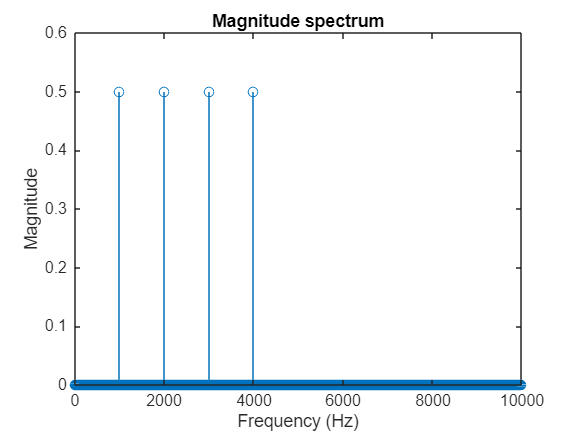


Y = Y(:);
freq = freq(:);

end

if window=="rect"
    y=y.*rectwin(length(y))'
elseif window=="hann"
    y=y.*hann(length(y))'
elseif window=="hamming" 
    y=y.*hamming(length(y))'
end
% Compute the frequency spectra of the signals

[Y, freqs] = make_spectrum(y, fs);

%make the magnitude spectra in dB
magnitude=abs(Y);
magnitude_dB= 20*log10(abs(Y));

Generated signal:

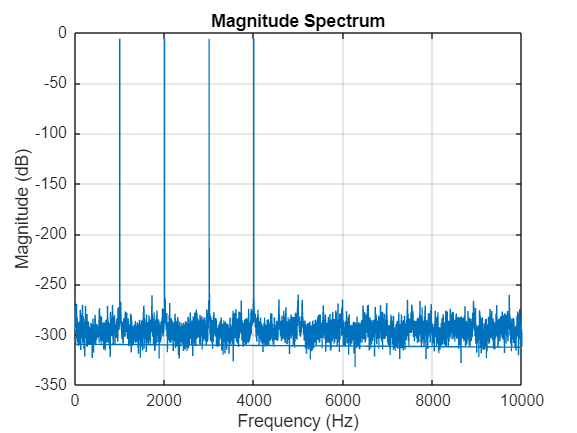

% plot the magnitude 
figure;
stem(freqs, magnitude)
title('Magnitude spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xmin=0;
xmax=fs/2;
xlim([xmin xmax]) ;

ymin=-1;
ymax=1;
ylim=([ymin, ymax]);

% Plot the magnitude spectrum in dB
figure;
plot(freqs, magnitude_dB);
title('Magnitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
grid on;
xmin=0;
xmax=fs/2;
xlim([xmin xmax])  ;
ymin=-1;
ymax=1;
ylim=([ymin, ymax]);

explain limits: nyquist frequency fs/2